Import Data

%% Import the data
close all; clear; clc;
% data = csvread('data164563.csv');
data = csvread('data133610.csv');

Error using csvread (line 35)
File not found.



gplotmatrix(data)
% Separate data into Inputs and output
X = data(:,1:(end-1));
Y = data(:,end);


Visualize Data

Error using clo (line 48)
Error while evaluating Figure SizeChangedFcn



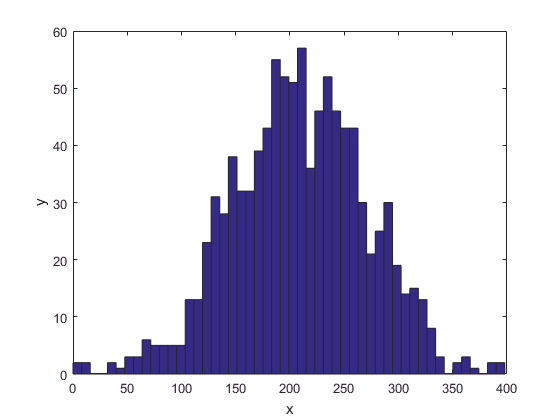

X1 = X(:,1); % Gaussian
X2 = X(:,2); % Guassian
X3 = X(:,3); % Uniform
X4 = X(:,4); % Uniform
X5 = X(:,5); % Uniform

figure(1);hist(X1,50);xlabel('x'),ylabel('y');

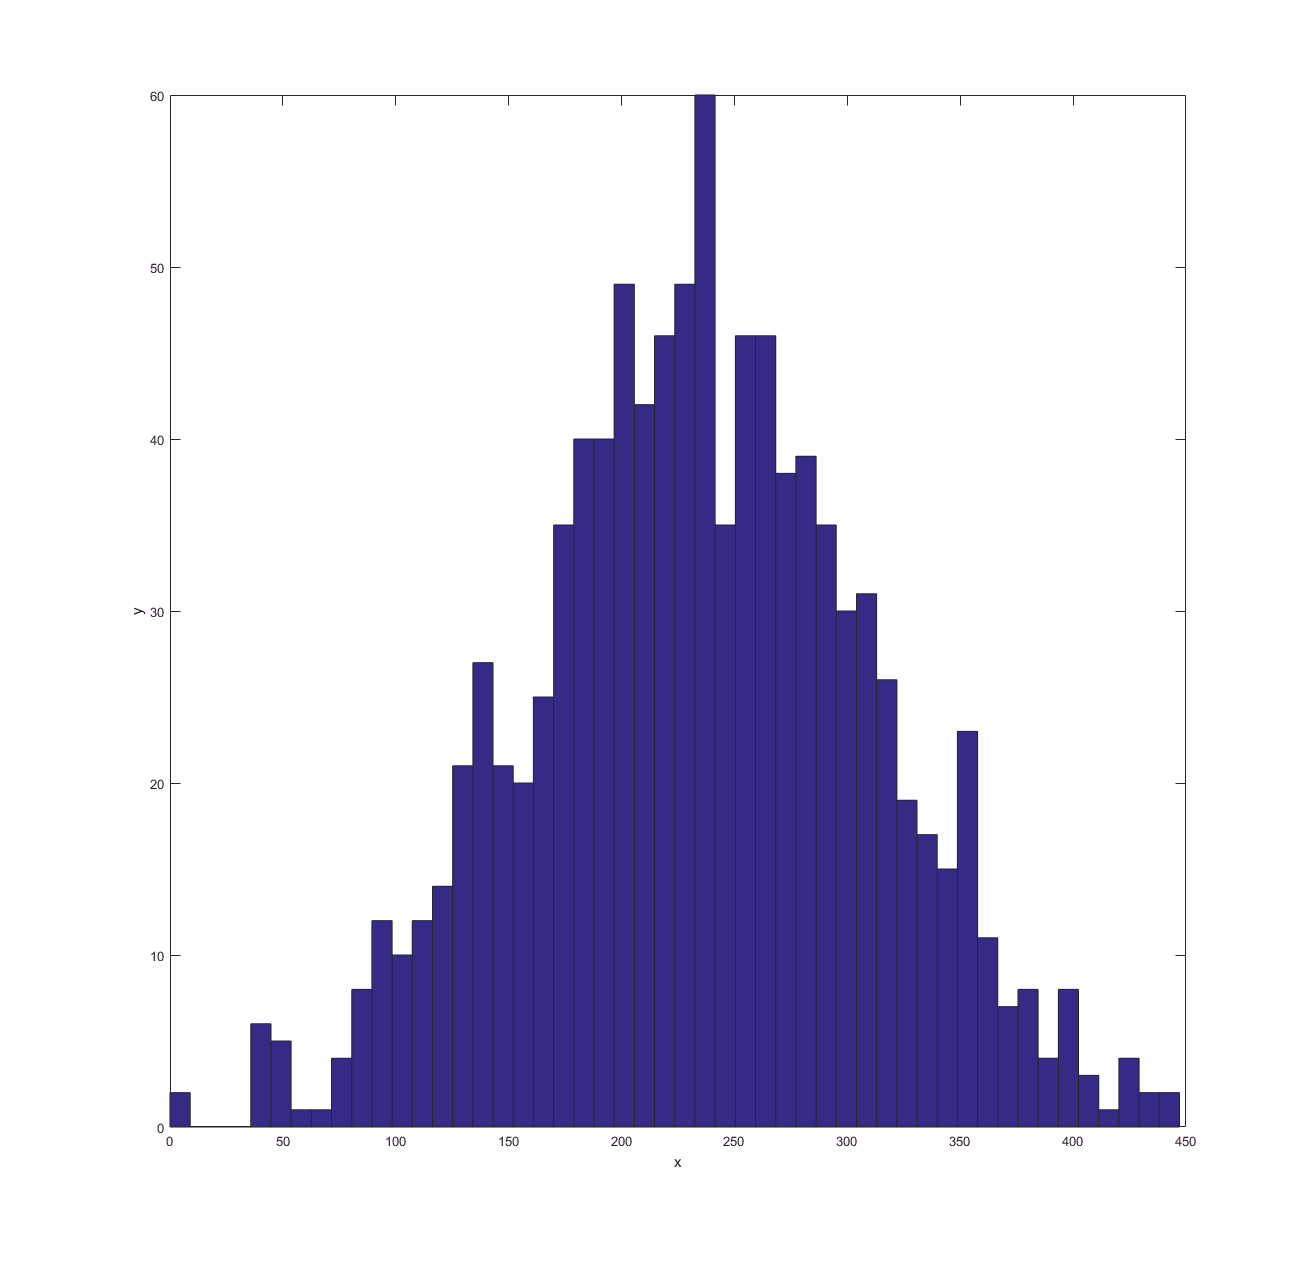

figure(2);hist(X2,50);xlabel('x'),ylabel('y');

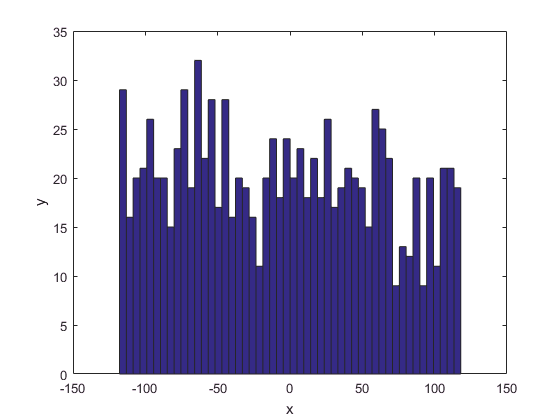

figure(3);hist(X3,50);xlabel('x'),ylabel('y');

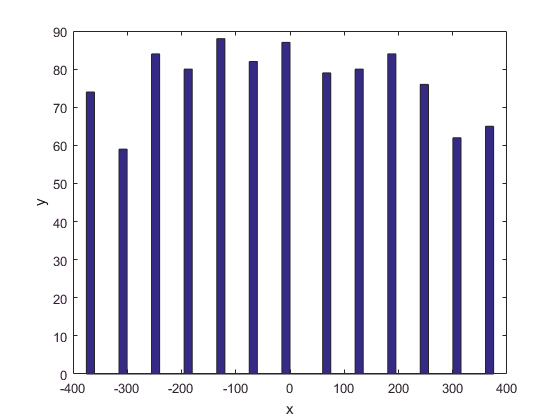

figure(4);hist(X4,50);xlabel('x'),ylabel('y');

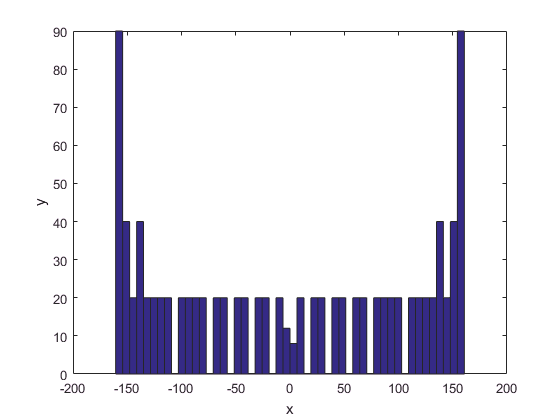

figure(5);hist(X5,50);xlabel('x'),ylabel('y');

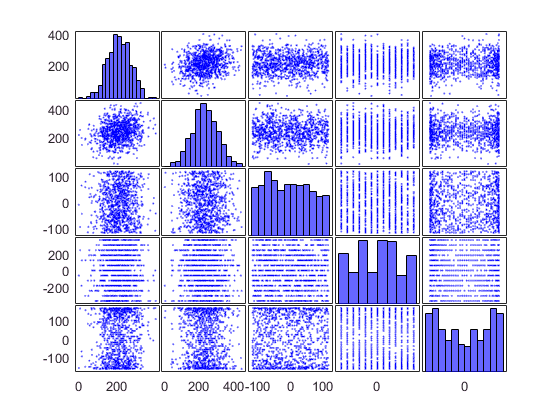


gplotmatrix(X)

Split Data into Test and Training data

trainS = 1;
trainF = 500;
testS = 501;
testF = 1000;

% Select features 1 and 2 as they corrolate with data

X_train = X(trainS:trainF,:);
Y_train = Y(trainS:trainF);
X_test = X(testS:testF,:);
Y_test = Y(testS:testF);

Normalize Data

[X_norm, X_avg, X_std] = featScale(X_train);

Apply PCA

covariance = cov(X_norm)

covariance =     1.0000    0.1984    0.0232   -0.0159    0.0201
    0.1984    1.0000   -0.0054   -0.0067    0.0423
    0.0232   -0.0054    1.0000    0.0016   -0.0098
   -0.0159   -0.0067    0.0016    1.0000   -0.0346
    0.0201    0.0423   -0.0098   -0.0346    1.0000


[U2,S2,V2] = svd(covariance);

% [u,v] = eig(cov(X_norm))

Xi = X_norm(:,1:2);
% Find the covariance matrix (sigma)
Sigma = (X'*X)/size(X,1)

Sigma =    1.0e+04 *

    4.7397    4.9924   -0.1062   -0.1141    0.0321
    4.9924    6.0677   -0.1471   -0.0966   -0.0134
   -0.1062   -0.1471    0.4586   -0.0160    0.0243
   -0.1141   -0.0966   -0.0160    5.0469   -0.1417
    0.0321   -0.0134    0.0243   -0.1417    1.2910


Sigma1 = cov(Xi)

Sigma1 =     1.0000    0.1984
    0.1984    1.0000



% compute eigenvectors of the covarience matrix (sigma)
[U,S,V] = svd(Sigma)

U =    -0.6585    0.0142    0.0266   -0.1412    0.7386
   -0.7518    0.0239   -0.0233    0.0998   -0.6509
    0.0180   -0.0048    0.0292   -0.9843   -0.1730
    0.0274    0.9989    0.0379   -0.0038    0.0031
   -0.0016   -0.0377    0.9982    0.0351   -0.0299


S =    1.0e+05 *

    1.0447         0         0         0         0
         0    0.5048         0         0         0
         0         0    0.1287         0         0
         0         0         0    0.0457         0
         0         0         0         0    0.0363


V =    -0.6585    0.0142    0.0266   -0.1412    0.7386
   -0.7518    0.0239   -0.0233    0.0998   -0.6509
    0.0180   -0.0048    0.0292   -0.9843   -0.1730
    0.0274    0.9989    0.0379   -0.0038    0.0031
   -0.0016   -0.0377    0.9982    0.0351   -0.0299


[U1,S1,V1] = svd(Sigma1)

U1 =    -0.7071   -0.7071
   -0.7071    0.7071


S1 =     1.1984         0
         0    0.8016


V1 =    -0.7071   -0.7071
   -0.7071    0.7071


%can also use
% U = eig(Sigma)
k = 1; % Number of dimentions to keep
Ureduce = U(:,1:k)

Ureduce =    -0.6585
   -0.7518
    0.0180
    0.0274
   -0.0016


z = Ureduce' * Xi'

Error using  * 
Inner matrix dimensions must agree.



% 1 - (Sum of 'k' S values)/(Sum of S values) must be smaller than 0.01 to retain 99% of data
% So don't use PCA

Visualize PCA Vectors

scatter3(z(3,:),z(4,:),Y)
scatter(z(4,:),Y)

Apply ICA

scatter3(X(:,1),X(:,2),Y)
xlabel('x')
ylabel('x2')
zlabel('y')

Create Model

lambda = 0.1

lambda = 0.1000


[weights, centers] = rbf_reg_weight(X_norm,Y_train, lambda);

trainOutput = rbf_reg_model(X_norm,centers,weights);
ETrain = meanSquaredError(Y_train,trainOutput)

ETrain = 8.3893e-04

X_test = featScaleTest(X_test,X_avg,X_std)

X_test =     4.2850    4.2349
    3.5229    3.8161
    5.2171    4.3091
    3.8500    4.6669
    2.5685    3.7307
    3.5730    2.9613
    1.7055    2.8588
    3.5964    3.0872
    3.2018    1.4532
    4.3664    3.8895


testOutput = rbf_reg_model(X_test,centers,weights);
ETest = meanSquaredError(Y_test,testOutput)

ETest = 0.0024


% % % Test Data
% % % 
% % % G = pdist2(centers,X_norm(testS:testF,1:2));
% % % testOutput = weights'*G;
% % % 
% % % Calculate Mean Squared Errors
% % % m = length(Y(testS:testF));
% % % ETest = (1/(m))*sum((testOutput-Y(testS:testF)').^2)
% % % Etest2 = meanSquaredError(testOutput,Y(testS:testF)')
% 
% fprintf('\n\n\n\n\n');
% pause;
% % Plot data
% 
% figure(1); scatter(x(:,1),Y,'g');
% hold on;
% scatter(x(trainS:trainF,1),trainOutput,'b');
% scatter(x(testS:testF,1),testOutput,'r');
% hold off;

Mean Squared Errors

VALS = crossval(FUN,X)

Luke, Test yours